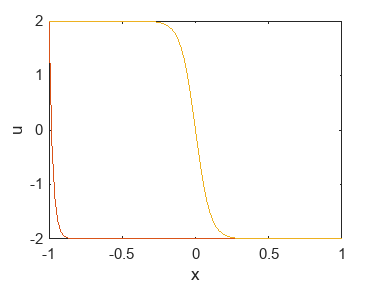

clc, close all;
clear;

n = 101;
%making the grid
x = linspace(-1,1,n);
delta = 2/n;

u1 = bvp(-4,.1,delta,n);
u2 = bvp(-4,.1,delta,n);
u3 = bvpSpecial(0,.1,delta,n);

figure("Name","Problem 1a: Boundary Layer and Shock Wave")
plot(x,u1);
hold on; 
plot(x,u2);
hold on;
plot(x,u3);
hold on;
xlabel('x')
ylabel('u')

function u = bvp(f,eps,delta,n)
    iMinusOneCoeff = -(f/(2*delta)+eps/delta^2);
    iCoeff = 2*eps/delta^2;
    iPlusOneCoeff = f/(2*delta)-eps/delta^2;
    
    a = iMinusOneCoeff.*ones(n,1); b = iCoeff.*ones(n,1); c = iPlusOneCoeff.*ones(n,1);
    b(1) = 1; c(1) = 0; a(n) = 0; b(n) = 1;
    d = zeros(n,1); d(1)=2; d(n) = -2;
    
    %Solving tridiagonal system
    u = THOMAS3(a,b,c,d,n);
end

function u = bvpSpecial(f,eps,delta,n)
    tol = 1e-7;
    correction = 1;
    uold = f.*ones(n,1)';
    unew = uold;
    while correction > tol
        a = -(uold./(2*delta)+eps./delta.^2);
        b = (2*eps/delta^2).*ones(1,n);
        c = uold./(2*delta)-eps./delta.^2;

        b(1) = 1; c(1) = 0; a(n) = 0; b(n) = 1;
        d = zeros(n,1); d(1)=2; d(n) = -2;

        %Solving tridiagonal system
        unew = THOMAS3(a,b,c,d,n);
        correction = max(abs(unew-uold));
        uold = unew;
    end
    u = unew;
end

% supporting function
function x = THOMAS3(a,b,c,d,n)

    %initial condition
    bbar(1) = b(1);
    cbar(1) = c(1);
    dbar(1) = d(1);

    %making upper triangle
    for i = 2:n
        multiplier = a(i)./bbar(i-1);
        abar(i) = a(i) - bbar(i-1).*multiplier;
        bbar(i) = b(i) - cbar(i-1).*multiplier;
        cbar(i) = c(i);
        dbar(i) = d(i) - dbar(i-1).*multiplier;
    end
    
    %initialize x of size n
    x = ones(1,n);

    %initialize end condition
    x(n) = dbar(n)/bbar(n);

    % Upward substitution AKA zip it up
    for i = n-1:-1:1
        x(i) = (dbar(i)-(cbar(i)*x(i+1)))/bbar(i);
    end
end